# Multi-Class Fault Detection Using Simulated Data

This example shows how to use a Simulink model to generate fault and healthy data. The data is used to develop a multi-class classifier to detect different combinations of faults. The example uses a triplex reciprocating pump model and includes leak, blocking, and bearing faults. 

## Setup the Model

This example uses many supporting files that are stored in a zip file. The setup script unzips the files needed to get access to the supporting files, loads the model parameters, and creates the reciprocating pump library. 

prj = currentProject;
pump_setup;

## Reciprocating Pump Model

The reciprocating pump consists of an electric motor, the pump housing, pump crank and pump plungers.

mdl = 'pdmRecipPump';
open_system(mdl)

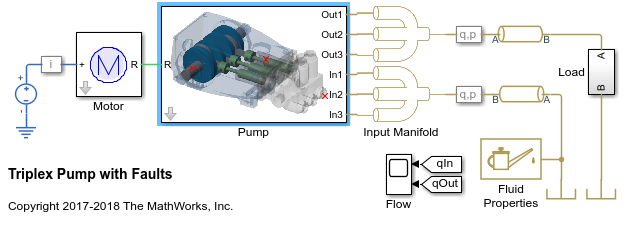

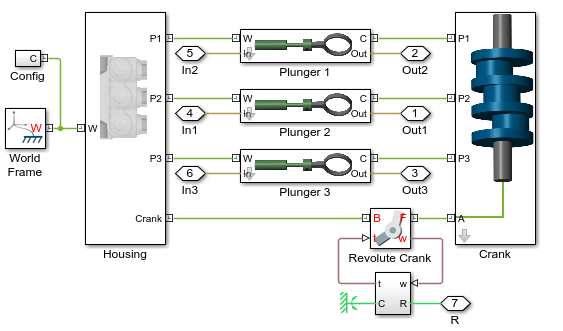

The pump model is configured to model three types of faults;  cylinder leaks, blocked inlet, and increased bearing friction. These faults are parameterized as workspace variables and configured through the pump block dialog.

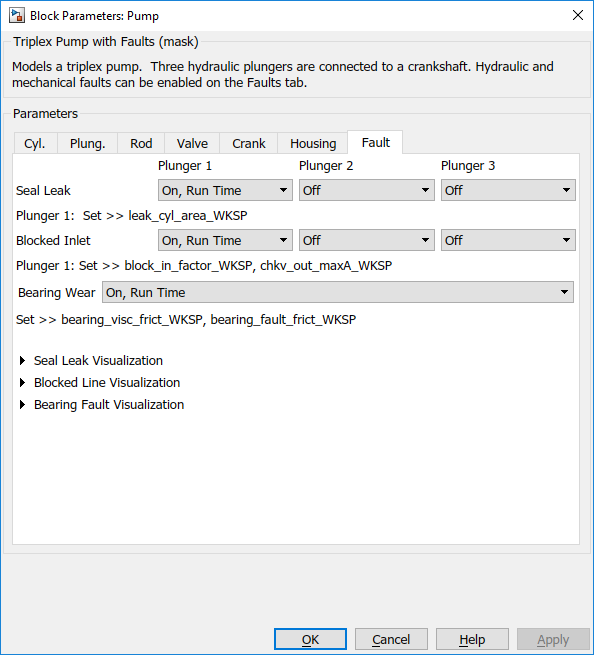

## Simulating Fault and Healthy Data

Create an array of values that represent how a blocked inlet fault can progress. In this example, we can model blockage failures spanning between 40-60 days. The blockage is represented in the model by the "passage area" parameter of a valve. As you might expect, we reduce the passage area to increase the severity of the blockage. We also assume that there are no other faults in the system and set the other parameters in the model accordingly.

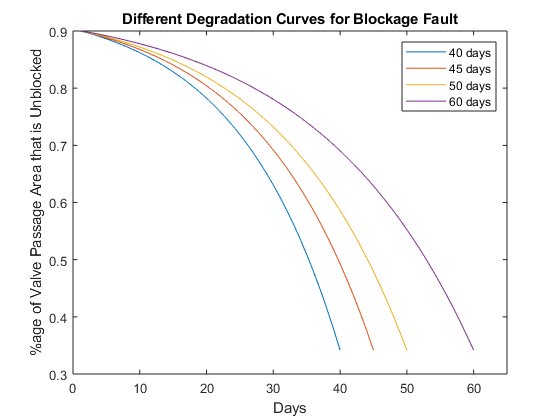

### Load Simulated Blockage Values

As an example, we can work with data from one of the pumps. Select the number of datasets to generate below.  

% use drop-down to suggest how many days until failure we want to simulate
daysToSimulate = 40;         % Choose pump failure spanning different number of days
blockage_vals_name = "block_"+num2str(daysToSimulate);
load("sim_param_values.mat","bearing_value",blockage_vals_name,"leak_value") % load the requested data from the .mat file
blockage_vals = eval(blockage_vals_name);

### Prepare Simulation

Next, we want to set up and run the simulations. (Note: Running the maximum number of days will take 10-15 minutes)

% Set some parameters in the model in case you forgot
prepModelForSim(mdl,daysToSimulate)

% Create our simulation input object
for ct = 1:daysToSimulate
    time_WKSP = ct;
    simInput(ct) = Simulink.SimulationInput(mdl); %#ok<*SAGROW> 
    simInput(ct) = setVariable(simInput(ct),'leak_cyl_area_WKSP',leak_value);
    simInput(ct) = setVariable(simInput(ct),'block_in_factor_WKSP',blockage_vals(ct));
    simInput(ct) = setVariable(simInput(ct),'bearing_fault_frict_WKSP',bearing_value);
    simInput(ct) = setVariable(simInput(ct),'noise_seed_offset_WKSP',ct-1);
    simInput(ct) = setVariable(simInput(ct),'time_WKSP',time_WKSP);
end

### Generate Synthetic Data

Use the `generateSimulationEnsemble` function to run the simulations defined by the `Simulink.SimulationInput` objects defined above and store the results in a local sub-folder. Then create a `simulationEnsembleDatastore` from the stored results. 

datapath = strcat(fullfile(prj.RootFolder,"Data_Generation", "Data"));
[ok, e] = generateSimulationEnsemble(simInput,datapath,'UseParallel',true);
ens = simulationEnsembleDatastore(datapath);
cleanupModel(mdl);

### Visualize Simulation Data

In Simulink toolstrip, click on **Data Inspector**.

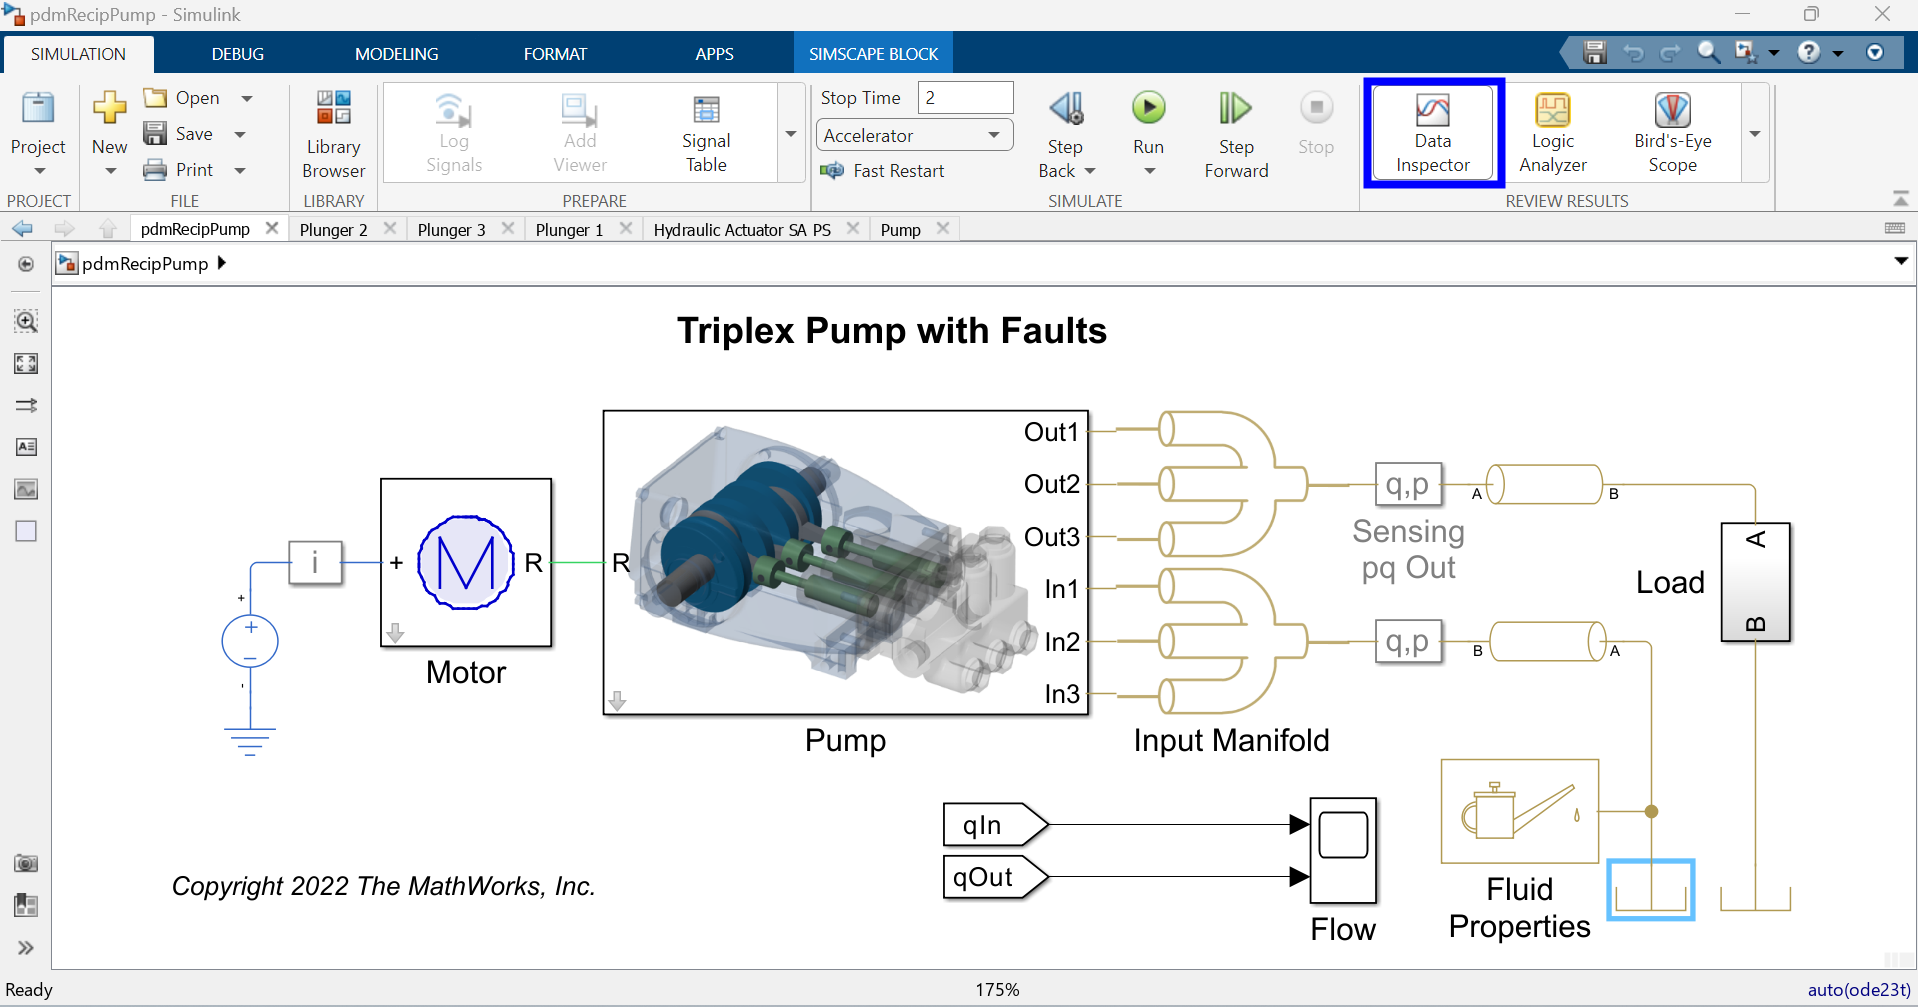

Change the plot layout to 4 rows and 1 column:

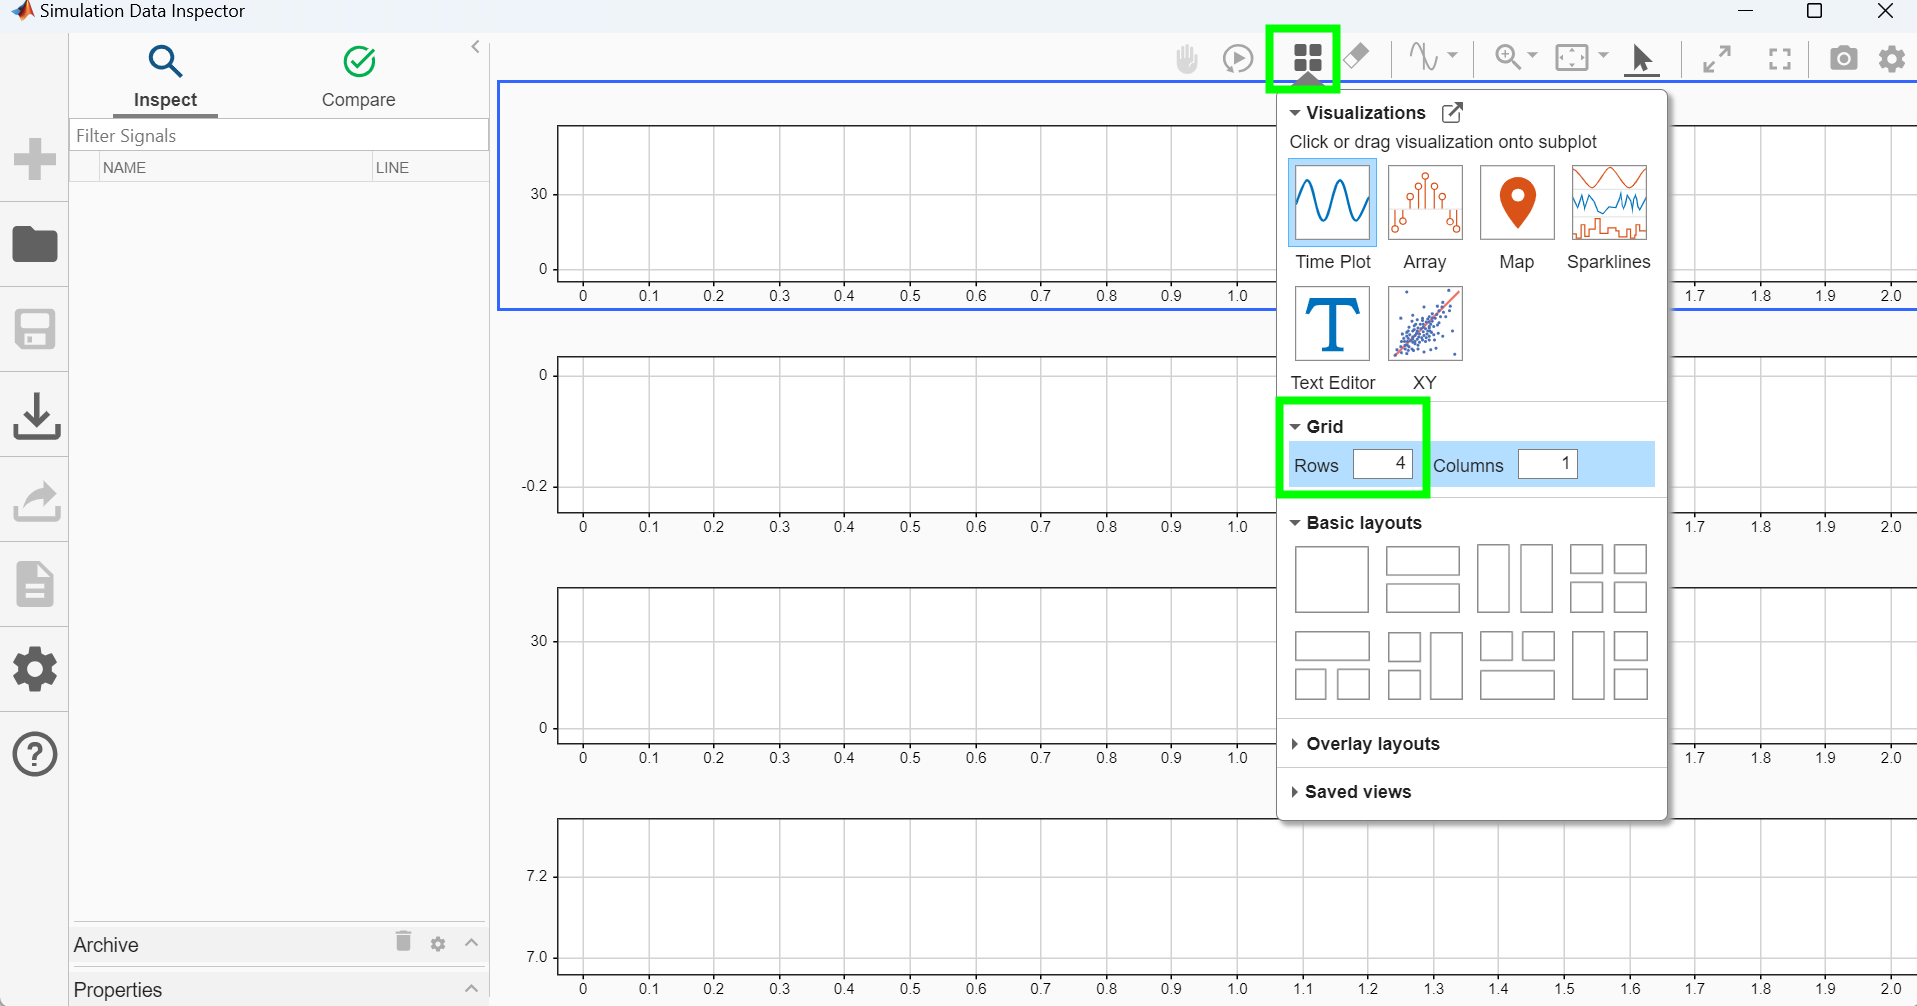

On the left sidebar, click on import:

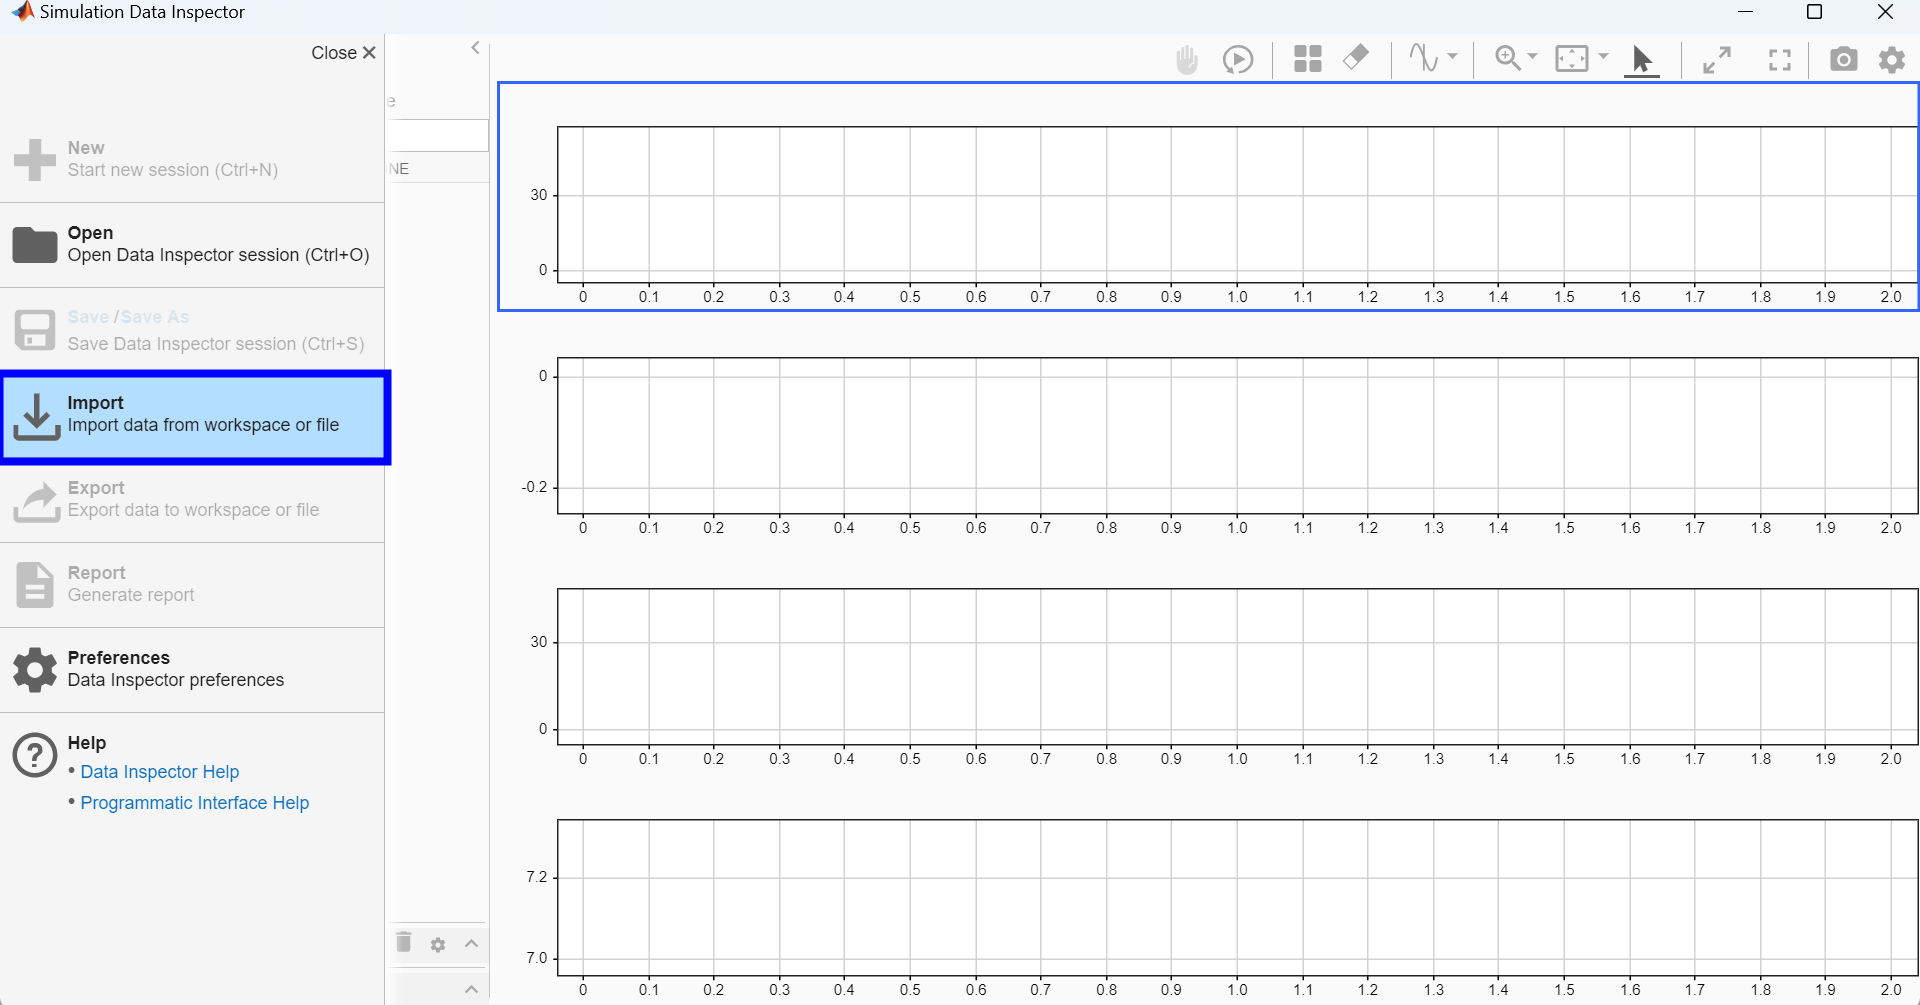

Locate the first log file produced in the "Data_Generation" -> "Data" folder, and click **Import**.

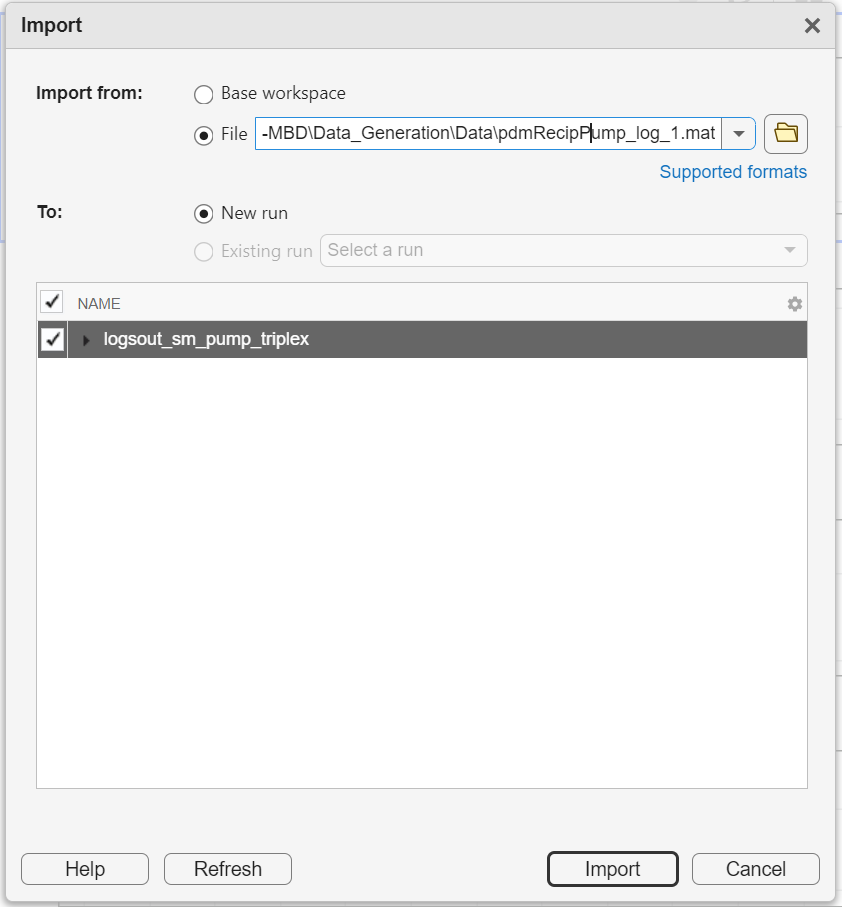

Double click on the Run name to change the name to "Sim1". Expand the selection and for each plot, select the signals as shown below:

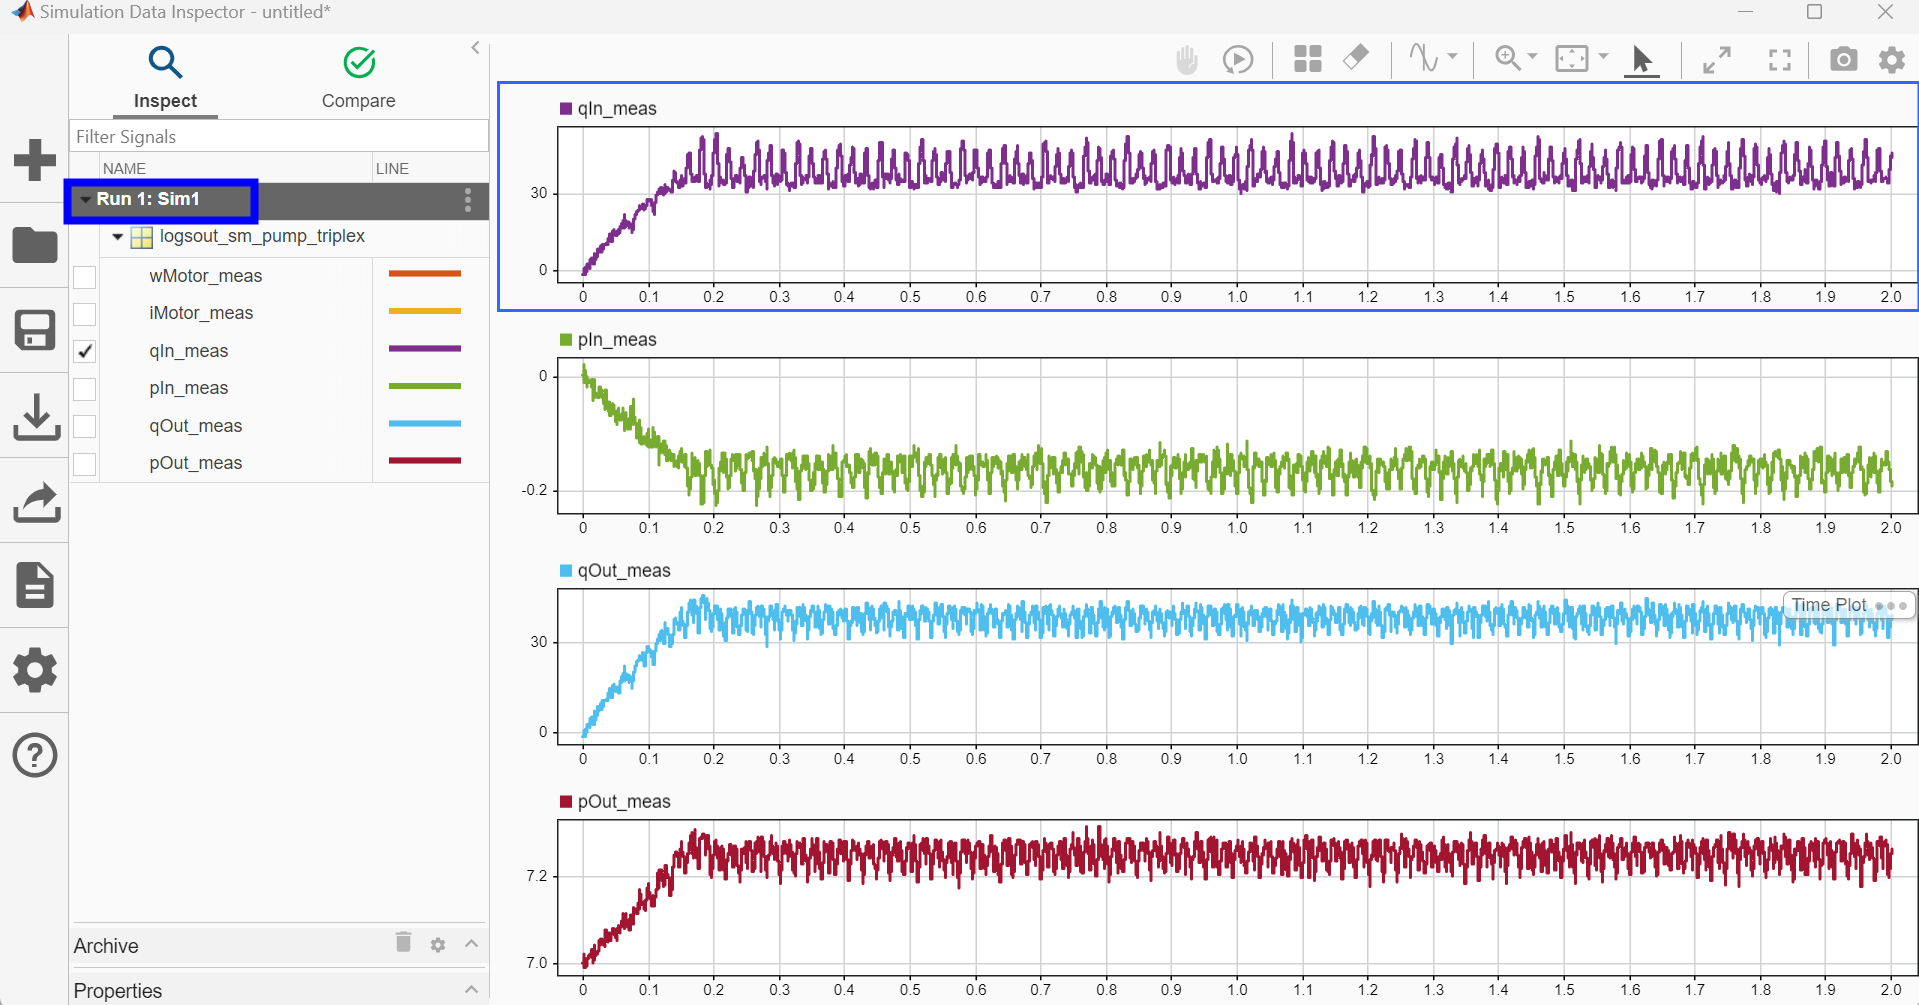

Click on Import again from the left sidebar:

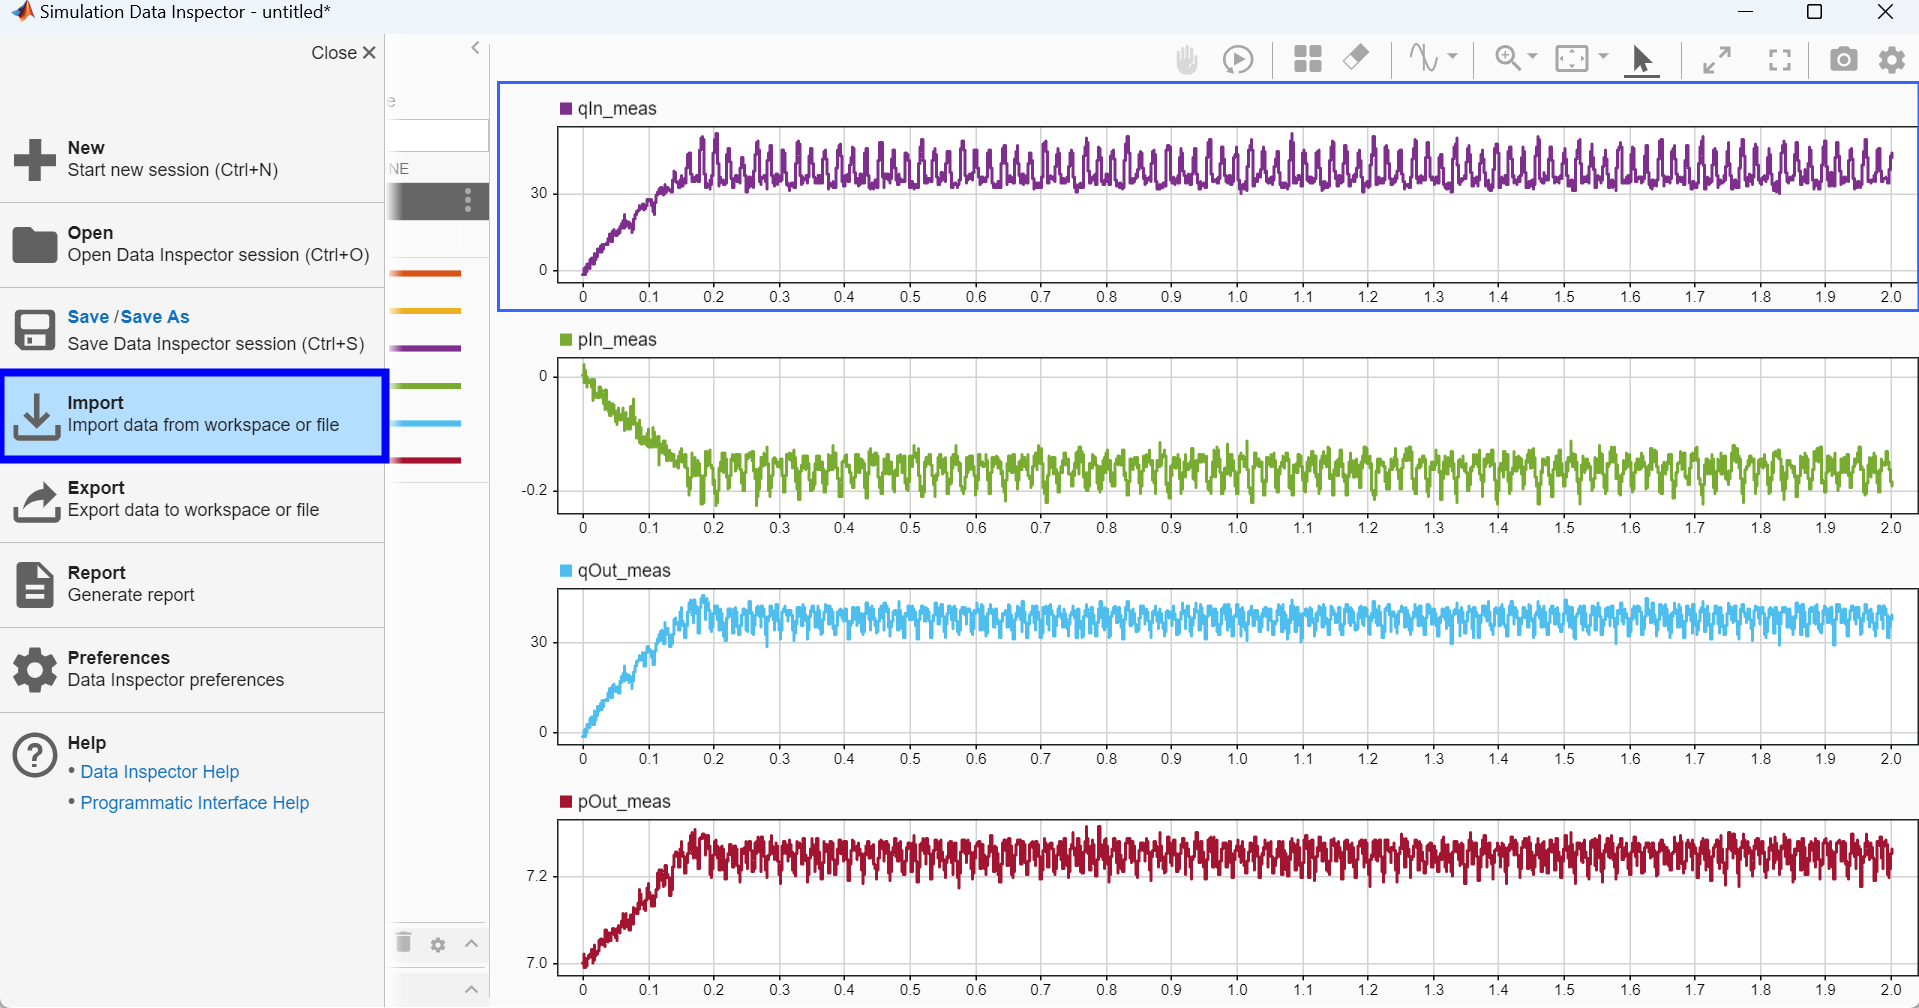

Locate the log file generated from the last simulation, and click **Import**.

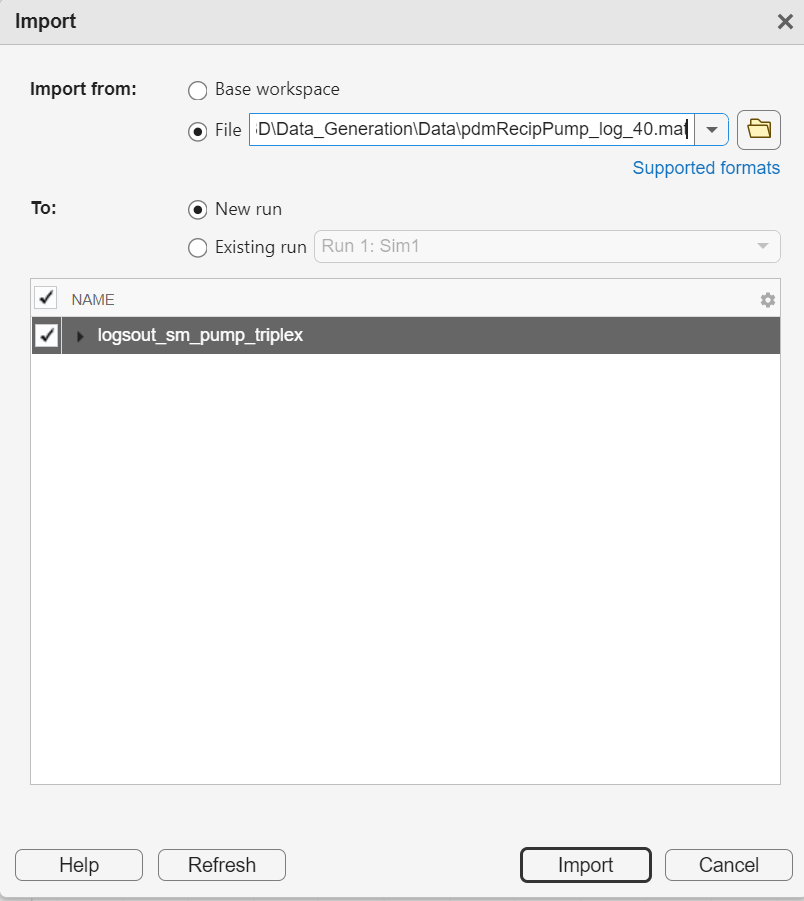

Double click on the Run name to change it to "Sim40":

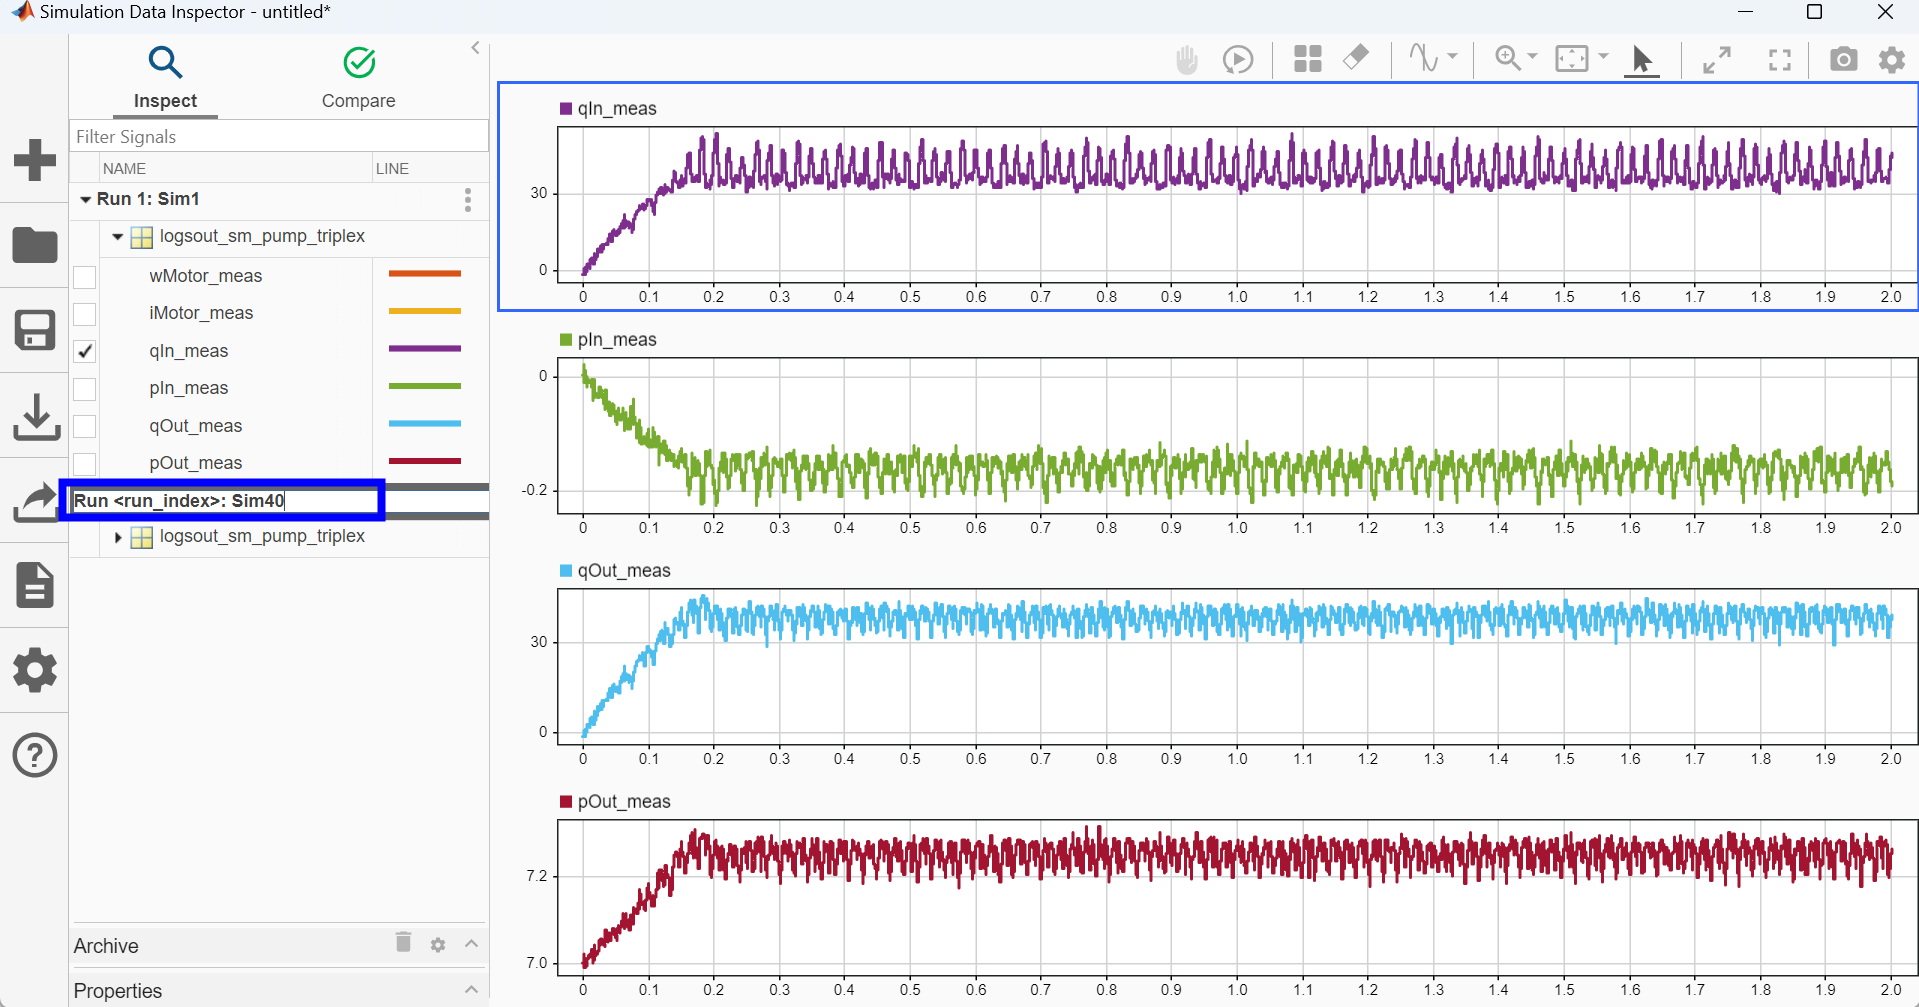

For each plot, first highlight the plot by clicking on the plot, and then select correponding signals from the last simulation, as shown below:

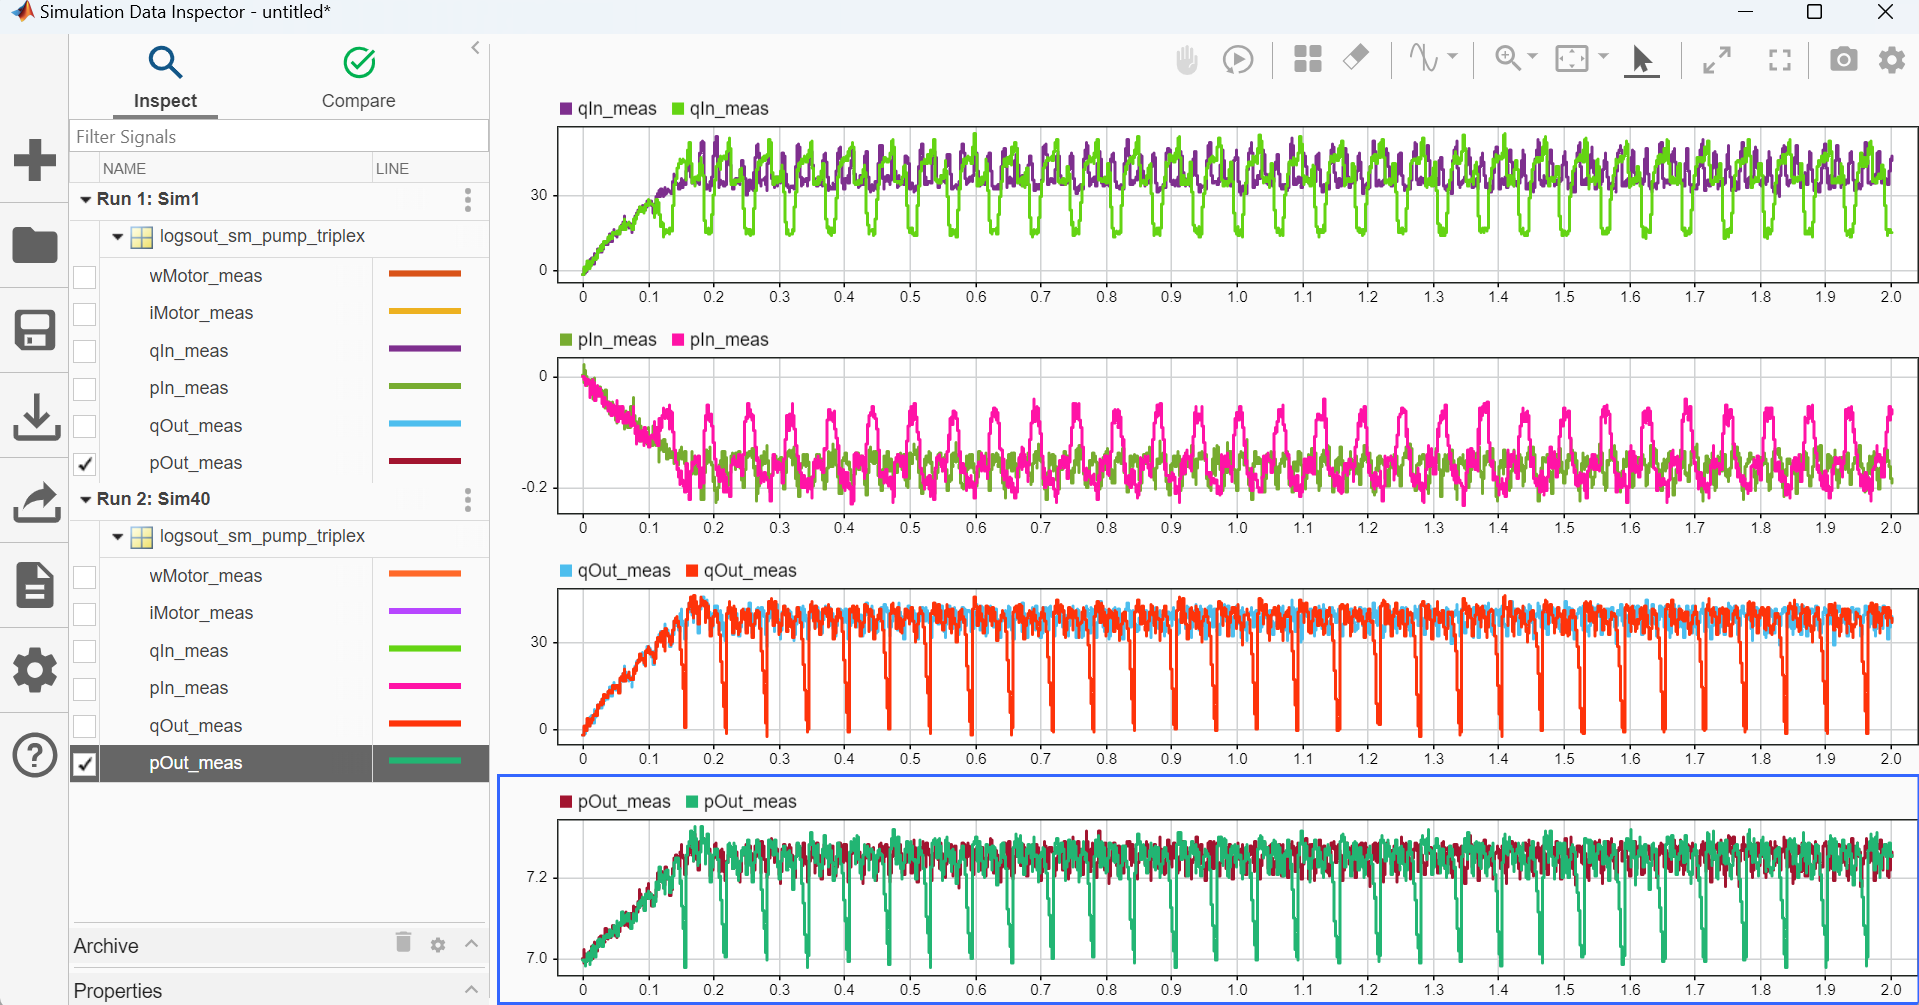

We can observe that the pump operations have degraded as we increase the severity of the inlet blockage.

**Optional**: you can also navigate to the "Compare" tab to investigate numerical differences between different pairs of signals and see how much they deviate from each other.

## Helper Functions

function prepModelForSim(mdl,daysToSimulate)
    % We don't need the mechanics viewer for multiple simulations
    if daysToSimulate>1
        set_param(mdl,'SimMechanicsOpenEditorOnUpdate','off');
        set_param(mdl,'SimulationMode','accelerator');
    end

    % turn "on" our faults (if you forgot).
    set_param([mdl,'/Pump'],'leak_cyl1_popup','On, Run Time')
    set_param([mdl,'/Pump'],'block_in_cyl1_popup','On, Run Time')
    set_param([mdl,'/Pump'],'bearing_fault_popup','On, Run Time')
    save_system
end

function cleanupModel(mdl)
    % turn "off" our faults (if you forgot). 
    set_param([mdl,'/Pump'],'leak_cyl1_popup','off')
    set_param([mdl,'/Pump'],'block_in_cyl1_popup','off')
    set_param([mdl,'/Pump'],'bearing_fault_popup','off')
    set_param(mdl,'SimMechanicsOpenEditorOnUpdate','on');
    
    save_system
end